# **Laboratorio 1**

**Experimentos**

%start enviroment
clear
clc

**    1.1. Hallar caracteristicas de la imagen**

I = imread('coins.png');

            Imagen a analizar

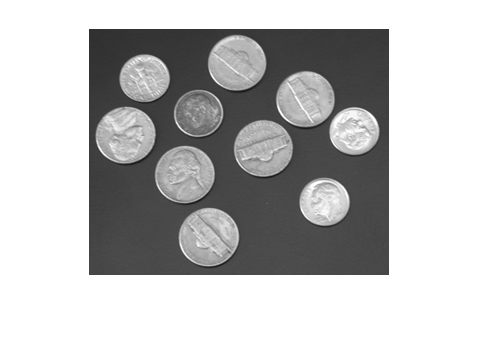

imshow(I)

            Obtenemos información de la imagen 

shapeI = whos; 

            Encontrar tamaño en bytes.

IBytes = shapeI.bytes;
fprintf('Tamaño en bytes: %i \n', IBytes)

Tamaño en bytes: 73800 


            Número de pixeles. 

IPixels = shapeI.size;
%fprintf('Distribución de pixeles: %d*%d', IPixels);
nPixels = IPixels(1,1)*IPixels(1,2);
fprintf('Número de pixeles: %i', nPixels);

Número de pixeles: 73800

            Número de bits por pixel.

bytesPorPixel = IBytes/nPixels;
bitsPorPixel = bytesPorPixel*(8/1);
fprintf('Número de bits por pixel: %i', bitsPorPixel);

Número de bits por pixel: 8

**    1.2. Comparar los tamaños de los archivos**

imwrite(I, 'coins.png');
imwrite(I, 'coins.jpg');
imwrite(I, 'coins5.jpg', 'quality', 5);

Ipng = imread('coins.png');
Ijpg = imread('coins.jpg');
Ijpg5 = imread('coins5.jpg');

whos Ipng

  Name        Size             Bytes  Class    Attributes

  Ipng      246x300            73800  uint8              



whos Ijpg

  Name        Size             Bytes  Class    Attributes

  Ijpg      246x300            73800  uint8              



whos Ijpg5

  Name         Size             Bytes  Class    Attributes

  Ijpg5      246x300            73800  uint8              



   ** 2.1. Caracteristicas de la imagen.**

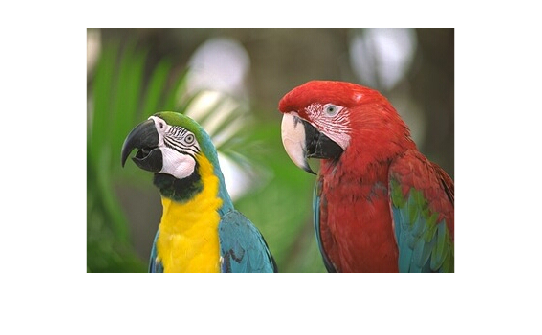

[I2, map] = imread("D:\HDSP\Lab1\parrots.tif");
imshow(I2)

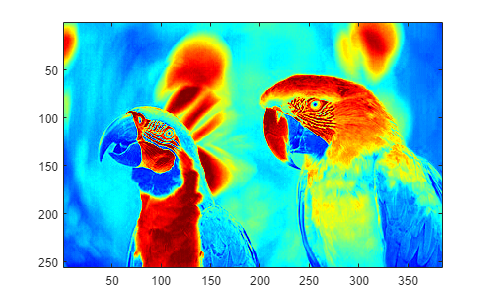


red = I2(:,:,1);
green = I2(:,:,2);
blue = I2(:,:,3);

imagesc(red)
colormap jet

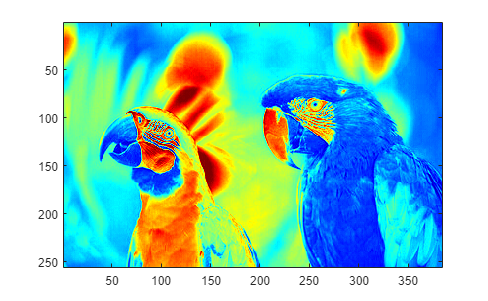

imagesc(green)
colormap jet

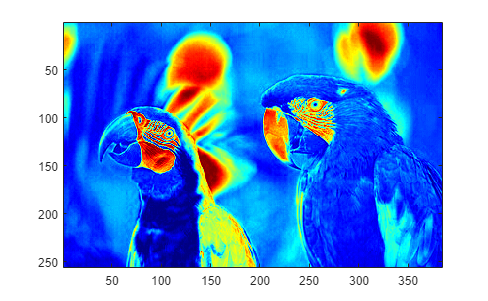

imagesc(blue)
colormap jet

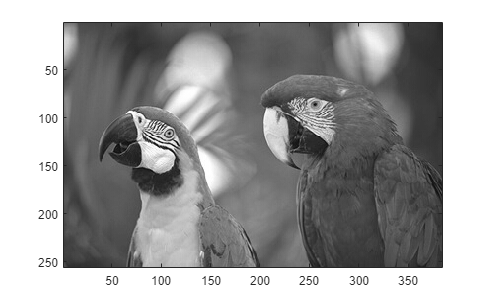


grayI2 = rgb2gray(I2);
imagesc(grayI2)
colormap gray

psnr_250 = psnr(grayI2,grayI2)

psnr_250 = Inf

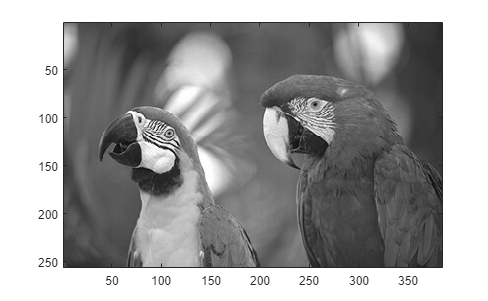


Nmax_200 = 200;
factor_200 = (255/Nmax_200);
grayI2_200 = grayI2/factor_200;
imagesc(grayI2_200)
colormap gray

whos grayI2_200

  Name              Size             Bytes  Class    Attributes

  grayI2_200      256x384            98304  uint8              



psnr_200 = psnr(grayI2_200,grayI2)

psnr_200 = 19.9755

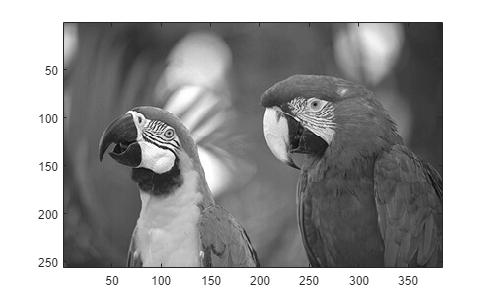


Nmax_100 = 100;
factor_100 = (255/Nmax_100);
grayI2_100 = grayI2/factor_100;
imagesc(grayI2_100)
colormap gray

whos grayI2_100

  Name              Size             Bytes  Class    Attributes

  grayI2_100      256x384            98304  uint8              



psnr_100 = psnr(grayI2_100,grayI2)

psnr_100 = 10.9762

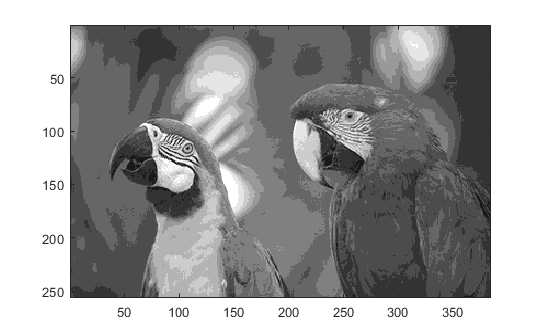


Nmax_10 = 10;
factor_10 = (255/Nmax_10);
grayI2_10 = grayI2/factor_10;
imagesc(grayI2_10)
colormap gray

whos grayI2_10

  Name             Size             Bytes  Class    Attributes

  grayI2_10      256x384            98304  uint8              



psnr_10 = psnr(grayI2_10,grayI2)

psnr_10 = 6.9995

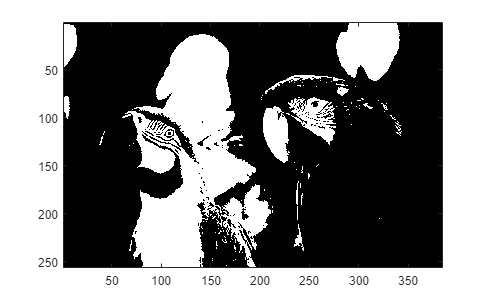


Nmax_1 = 1;
factor_1 = (255/Nmax_1);
grayI2_1 = grayI2/factor_1;
imagesc(grayI2_1)
colormap gray

whos grayI2_10

  Name             Size             Bytes  Class    Attributes

  grayI2_10      256x384            98304  uint8              



psnr_1 = psnr(grayI2_10,grayI2)

psnr_1 = 6.9995

**2.2. Grafique la variación del PSNR en funcion de  N**

% Funcion PSNR
MSE = immse(grayI2_200,grayI2);
peakval = 255;
PSNR=10*log10(peakval^2/MSE)

PSNR = 19.9755


%Pasar a double para poder usarla dentro del for
grayI2_d = im2double(grayI2)*255;

%En funcion de N
N = 200;
factor_N = (255/N);
grayI2_N = grayI2/factor_N;
grayI2_N = im2double(grayI2_N)*255;

suma2 = 0;

for i = 1:256
    for j = 1:384
        suma2 = suma2 + ( grayI2_d(i,j) - grayI2_N(i,j))^2;
    end
end

mse2 = (suma2/98304);
PSNR2=10*log10(peakval^2/mse2)

PSNR2 = 19.9755


%Probar si mse es lo mismo para 1 o muchos valores
MSE_completo = immse(grayI2_200,grayI2)

MSE_completo = 653.9294

MSE_un_valor = immse(200,255)

MSE_un_valor = 3025

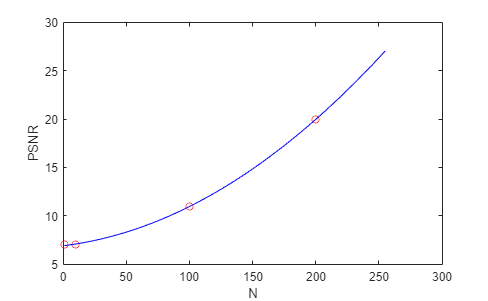


%Obtener todo en funcion de mse en funcion de N usando valores y polyfit
%Mses
% MSE_1 = immse(grayI2_1,grayI2);
% MSE_10 = immse(grayI2_10,grayI2);
% MSE_100= immse(grayI2_100,grayI2);
% MSE_200= immse(grayI2_200,grayI2);
% MSE_255= immse(grayI2,grayI2);

% N_vector = [ 1 10 100 200 255 ];
% mse_vector = [ MSE_1 MSE_10 MSE_100 MSE_200 MSE_255 ];

%aproximación
% NfunctionMse = polyfit(N_vector, mse_vector,2);

%graficamos
% xN = 1:255;
% yN = polyval(NfunctionMse,xN);

% plot (N_vector,mse_vector,'ro')
% hold on 
% plot (xN, yN, 'b')

%Obtener Psnr en funcion de mse graficando
%Aca descubro la opción 2: hacer psnr en funcion de N de una vez
N_vector = [ 1 10 100 200 ];
psnr_vector = [ psnr_1 psnr_10 psnr_100 psnr_200 ];

%aproximación
NfunctionPsnr = polyfit(N_vector, psnr_vector,2);

%graficamos 
xN = 1:255;
yN = polyval(NfunctionPsnr,xN);

plot (N_vector,psnr_vector,'ro')
hold on 
plot (xN, yN, 'b')
ylabel('PSNR')
xlabel('N')
hold off

%recordar que en 255 tenemos una asintota

**Grafique el tamaño de la imagen en función de N**

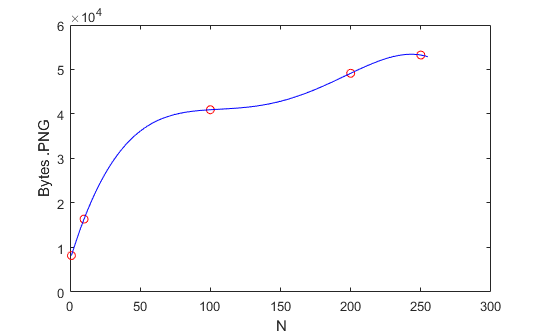

%tamaño PNG
imwrite(grayI2_1, 'D:\HDSP\Lab1\images\grayI2_1.png');
imwrite(grayI2_10, 'D:\HDSP\Lab1\images\grayI2_10.png');
imwrite(grayI2_100, 'D:\HDSP\Lab1\images\grayI2_100.png');
imwrite(grayI2_200, 'D:\HDSP\Lab1\images\grayI2_200.png');
imwrite(grayI2, 'D:\HDSP\Lab1\images\grayI2_255.png');

N_vector = [ 1 10 100 200 250];
png_vector = [ 8192 16384 40960 49152 53248];

%aproximación
NfunctionPng = polyfit(N_vector, png_vector,4);

%graficamos 
xN = 1:255;
yN = polyval(NfunctionPng,xN);

plot (N_vector,png_vector,'ro')
hold on 
plot (xN, yN, 'b')
ylabel('Bytes .PNG')
xlabel('N')
hold off

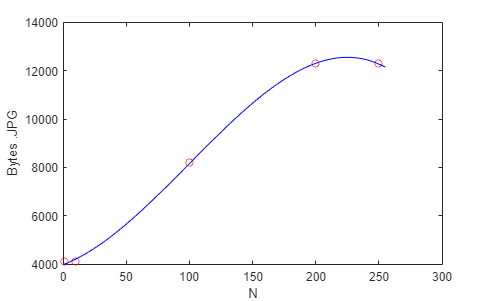


%tamaño JPG
imwrite(grayI2_1, 'D:\HDSP\Lab1\images\grayI2_1.jpg');
imwrite(grayI2_10, 'D:\HDSP\Lab1\images\grayI2_10.jpg');
imwrite(grayI2_100, 'D:\HDSP\Lab1\images\grayI2_100.jpg');
imwrite(grayI2_200, 'D:\HDSP\Lab1\images\grayI2_200.jpg');
imwrite(grayI2, 'D:\HDSP\Lab1\images\grayI2_255.jpg');

N_vector = [ 1 10 100 200 250];
jpg_vector = [ 4096 4096 8192 12288 12288 ];

%aproximación
NfunctionJpg = polyfit(N_vector, jpg_vector,3);

%graficamos 
xN = 1:255;
yN = polyval(NfunctionJpg,xN);

plot (N_vector,jpg_vector,'ro')
hold on 
plot (xN, yN, 'b')
ylabel('Bytes .JPG')
xlabel('N')
hold off

**3. Realizar una función en matlab que contruya y visualice una imagen de 256x256 con variación de N niveles de grises en filas y columnas.**

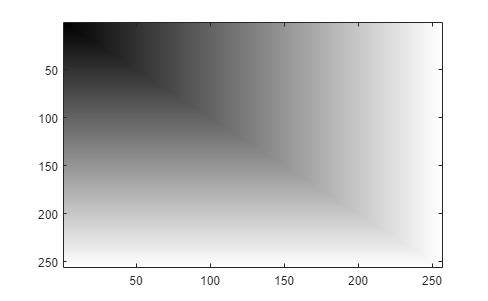

N=256;
Imagen = ones(N);

for i = 1:N
    for j = 1:i
        Imagen(i,i)=(i-1)/(255/N);
        Imagen(i,j)=(i-1)/(255/N);
        Imagen(j,i)=(i-1)/(255/N);
    end
end

imagesc(Imagen)
colormap gray

**4. Realizar una función en matlab que contruya y visualice una imagen de 256x256 con variación de N niveles en filas y columnas desde el color azul al color rojo. Recuerde que el color rojo se define en RGB como [255 0 0] y el color azul como [0 0 255].**

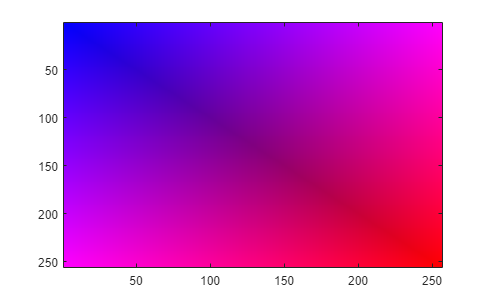

N=256;
R = zeros(N);
G = zeros(N);
B = zeros(N);


for i = 1:N
        for j = 1:i
            R(i,i)=(0+i)/N;
            R(i,j)=(0+i)/N;
            R(j,i)=(0+i)/N;
            B(N-i+1,N-i+1)=(0+i)/N;
            B(N-i+1,N-j+1)=(0+i)/N;
            B(N-j+1,N-i+1)=(0+i)/N;
        end
end

RGB1(:,:,1) = R;
RGB1(:,:,2) = G*0;
RGB1(:,:,3) = B;
imagesc(RGB1)

**5. Escribir una función en Matlab que cree una figura sobre una matriz binaria. La figura puede ser un cuadrado, un rectangulo, un triangulo o un circulo. La funci´on debe cumplir el siguiente formato:**

[Ifinal] = figura('rectangulo');

rectangulo


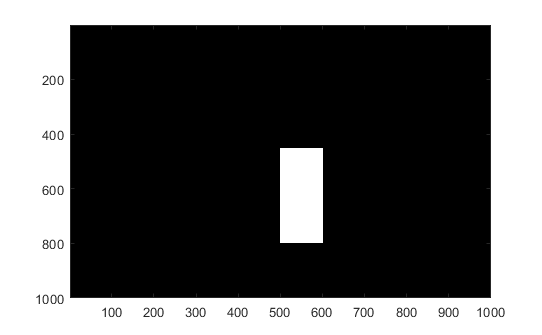

Ifinal = im2bw(Ifinal,0.5);
imagesc(Ifinal)

function [I] = figura(stringfigura)
% Genera una imagen binaria con la forma ’stringfigura’;
% --------------------------------------------------
% stringfigura = ’cuadrado’, ’circulo’, triangulo’, ’rectangulo’ o ’todos’;

N=1000;
I = zeros(N);

switch stringfigura

    case 'cuadrado'
        disp('cuadrado')
        for i = 200:300
            for j = 200:i
                I(i,j)=1;
                I(j,i)=1;
            end
        end

    case 'circulo'
        disp('circulo')
        for i = 500:600
%             I(i,500)=1;
            for j = 1:350
                I(450+j,i)=1;
            end
        end
    case 'triangulo'
        disp('triangulo')

    case 'rectangulo'
        disp('rectangulo')
        for i = 500:600
            for j = 1:350
                I(450+j,i)=1;
            end
        end

    case 'todos'
        disp('todos')

    otherwise
        disp('invalido')
end
    

end

